# Deep Learning

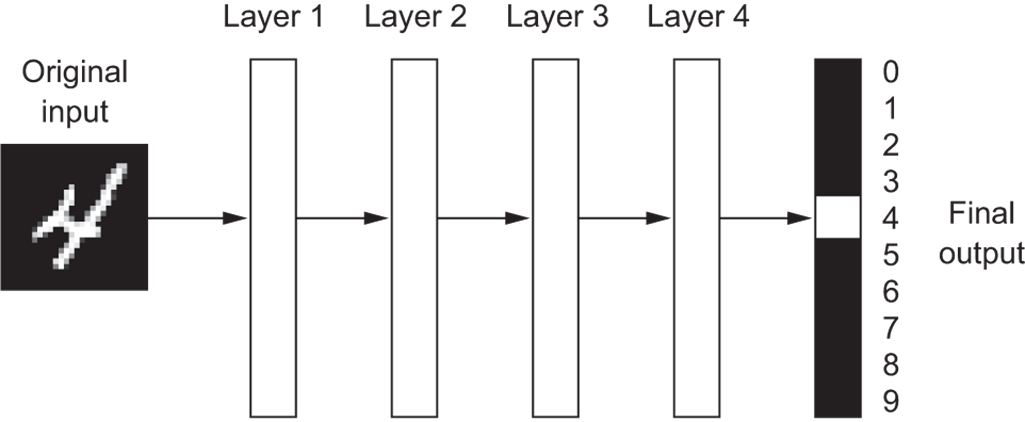

## เตรียมข้อมูลทดสอบ

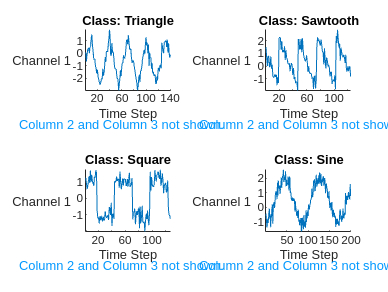

load('WaveformData.mat')

numChannels = size(data{1},2);

idx = [3 4 5 12];
figure
tiledlayout(2,2)
for i = 1:4
    nexttile
    stackedplot(data{idx(i)},DisplayLabels="Channel " + string(1:numChannels))
    
    xlabel("Time Step")
    title("Class: " + string(labels(idx(i))))
end

แยก channel ออกเป็นข้อมูลแต่ละตัว เนื่องจากเราต้องการทดสอบกับข้อมูลเสียง 1 channel เท่านั้น

numObservations = numel(data);
newData = cell(3 * numObservations, 1);
for i = 1:numObservations
    newData{(i-1) * 3 + 1} = data{i}(:,1);
    newData{(i-1) * 3 + 2} = data{i}(:,2);
    newData{(i-1) * 3 + 3} = data{i}(:,3);
end
newLabels = repelem(labels, 3);

% Shuffle new data
numObservations = numel(newData);
idx = randperm(numObservations);
newData = newData(idx);
newLabels = newLabels(idx);

แบ่งข้อมูลออกเป็นชุดฝึกฝน (training set) ชุดตรวจสอบ (validation set) และชุดทดสอบ (test set) ในสัดส่วน 0.8:0.1:0.1

% Split training data into a training set and a test set
partition = cvpartition(newLabels, 'Holdout', 0.2);

idxTrain = training(partition);
idxTest = test(partition);

XTrain = newData(idxTrain);
yTrain = newLabels(idxTrain);

XTest = newData(idxTest);
yTest = newLabels(idxTest);

% Split the test set further into a validation set and a smaller test set
partition = cvpartition(yTest, 'Holdout', 0.5);

idxVal = training(partition);
idxTest = training(partition);

XVal = XTest(idxVal);
yVal = yTest(idxVal);

XTest = XTest(idxTest);
yTest = yTest(idxTest);

## Multilayer perceptron (MLP)

- Fully-connected neurons

- Nonlinear activation functions

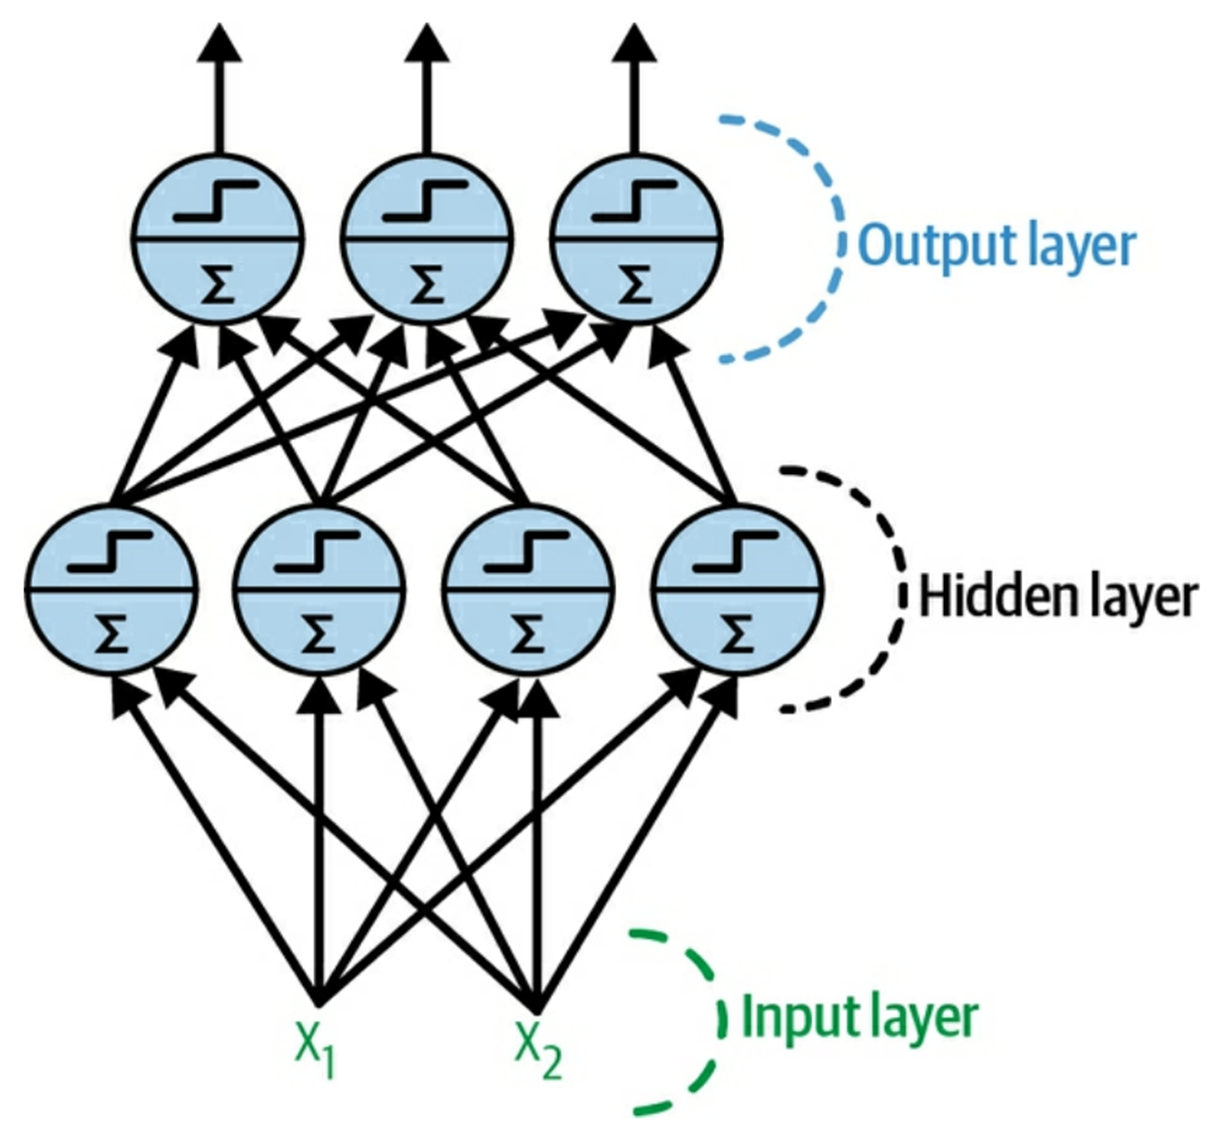

minLength = min(cellfun(@(x) size(x, 1), data));

% Raw signal
% FTrain = cell2mat(cellfun(@(x) x(1:minLength)', XTrain, 'UniformOutput', false));
% FVal = cell2mat(cellfun(@(x) x(1:minLength)', XVal, 'UniformOutput', false));
% FTest = cell2mat(cellfun(@(x) x(1:minLength)', XTest, 'UniformOutput', false));

% FFT amplitude
FTrain = cell2mat(cellfun(@(x) abs(fft(x(1:minLength)')), XTrain, 'UniformOutput', false));
FVal = cell2mat(cellfun(@(x) abs(fft(x(1:minLength)')), XVal, 'UniformOutput', false));
FTest = cell2mat(cellfun(@(x) abs(fft(x(1:minLength)')), XTest, 'UniformOutput', false));

classNames = categories(yTrain);
numClasses = numel(classNames);

layers = [ ...
    featureInputLayer(minLength)
    fullyConnectedLayer(64)
    reluLayer
    fullyConnectedLayer(32)
    reluLayer
    fullyConnectedLayer(numClasses)
    softmaxLayer]

layers =   7×1 Layer array with layers:

     1   ''   Feature Input     101 features
     2   ''   Fully Connected   64 fully connected layer
     3   ''   ReLU              ReLU
     4   ''   Fully Connected   32 fully connected layer
     5   ''   ReLU              ReLU
     6   ''   Fully Connected   4 fully connected layer
     7   ''   Softmax           softmax

options = trainingOptions("adam", ...
    MaxEpochs=60, ...
    MiniBatchSize=64, ...
    InitialLearnRate=0.01, ...
    SequencePaddingDirection="left", ...
    ValidationData={FVal, yVal}, ...
    Plots="training-progress", ...
    Metrics="accuracy", ...
    Verbose=false);

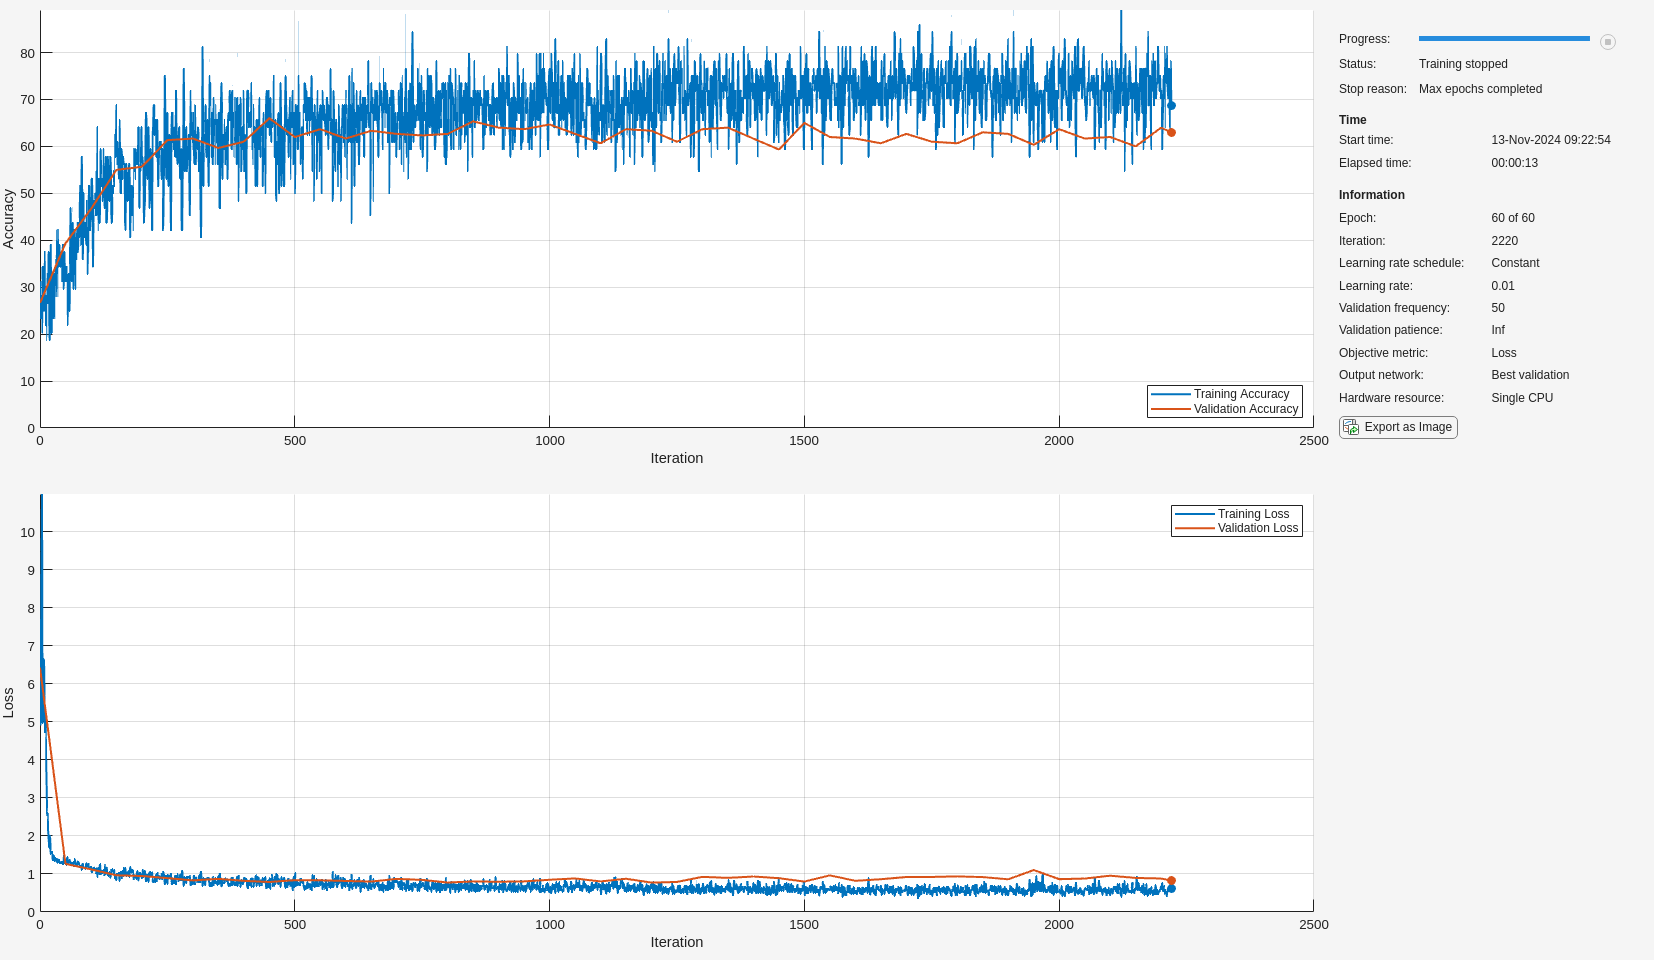

net = trainnet(FTrain, yTrain, layers, "crossentropy", options);

ทดสอบผลลัพธ์

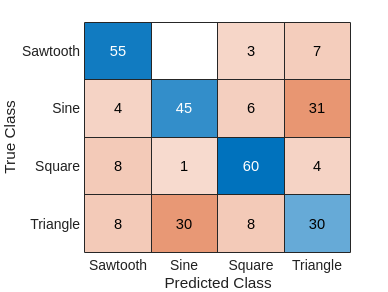

scores = minibatchpredict(net, FTest, SequencePaddingDirection="left");
yPred = scores2label(scores, classNames);
figure
confusionchart(yTest, yPred)

Precision = TP / (TP + FP)

Recall = TP / (TP + FN)

F1-score = 2 * Precision * Recall / (Precision + Recall)

% Compute accuracy
[m, cats] = confusionmat(yTest, yPred);
numCorrect = sum(diag(m));
accuracy = numCorrect / numel(XTest)

accuracy = 0.6333


% Precision, recall, and F1-score
tp = diag(m);
precision = tp ./ sum(m, 2)

precision =     0.8462
    0.5233
    0.8219
    0.3947


recall = tp ./ sum(m, 1)'

recall =     0.7333
    0.5921
    0.7792
    0.4167


f1 = 2 .* precision .* recall ./ (precision + recall)

f1 =     0.7857
    0.5556
    0.8000
    0.4054


f1Mean = mean(f1)

f1Mean = 0.6367

## Convolutional neural networks (CNN)

### กระบวนการ convolution

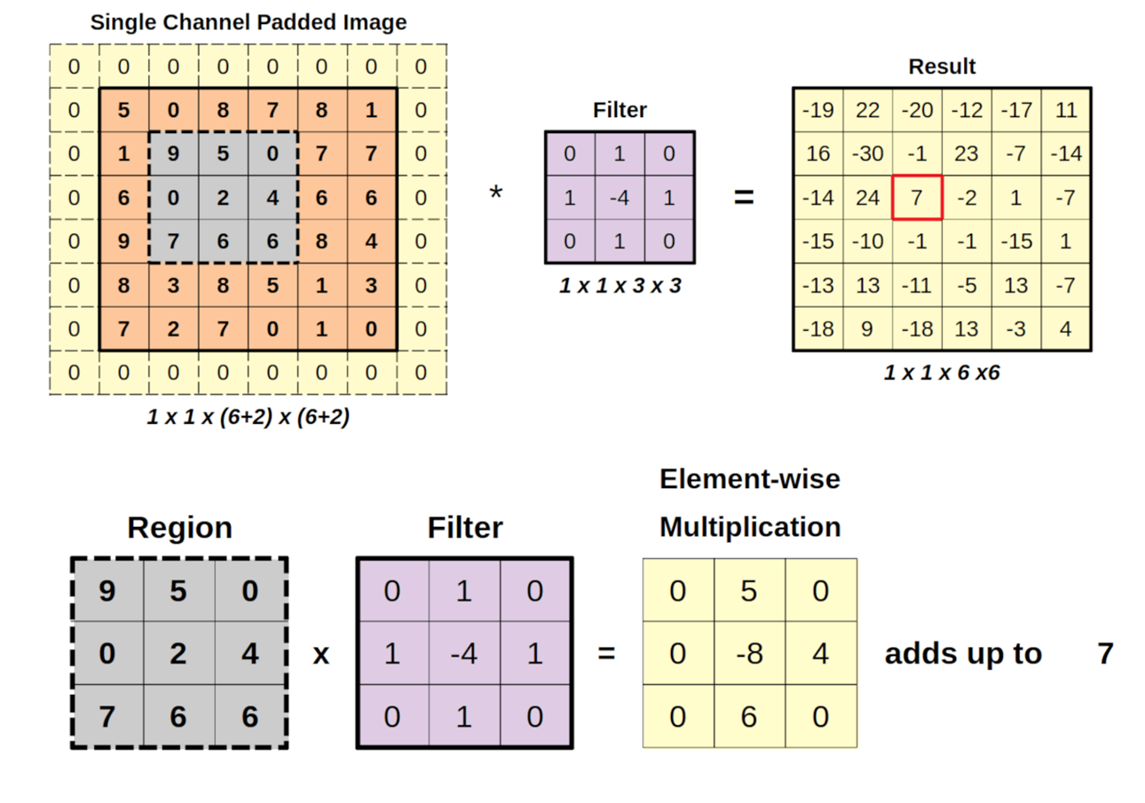

### ผลลัพธ์ในแต่ละชั้น

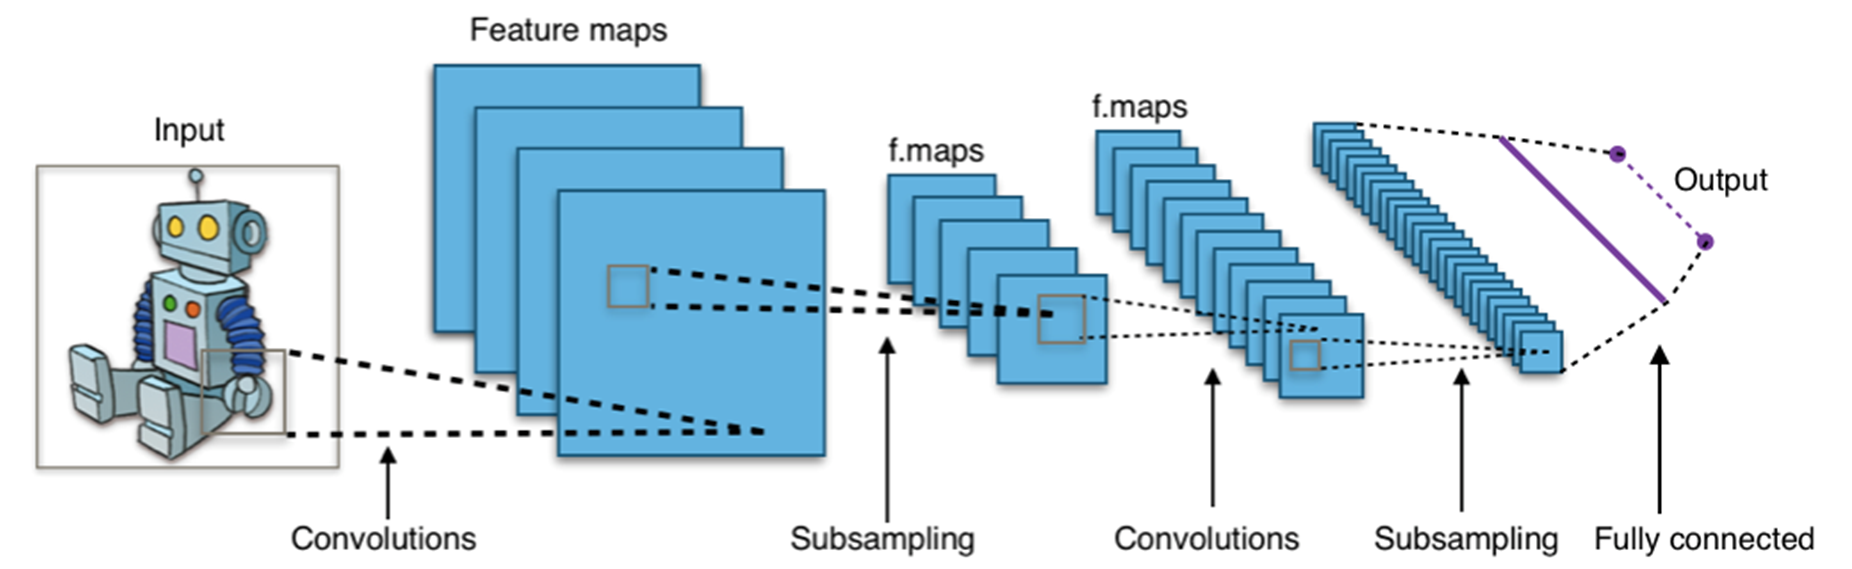

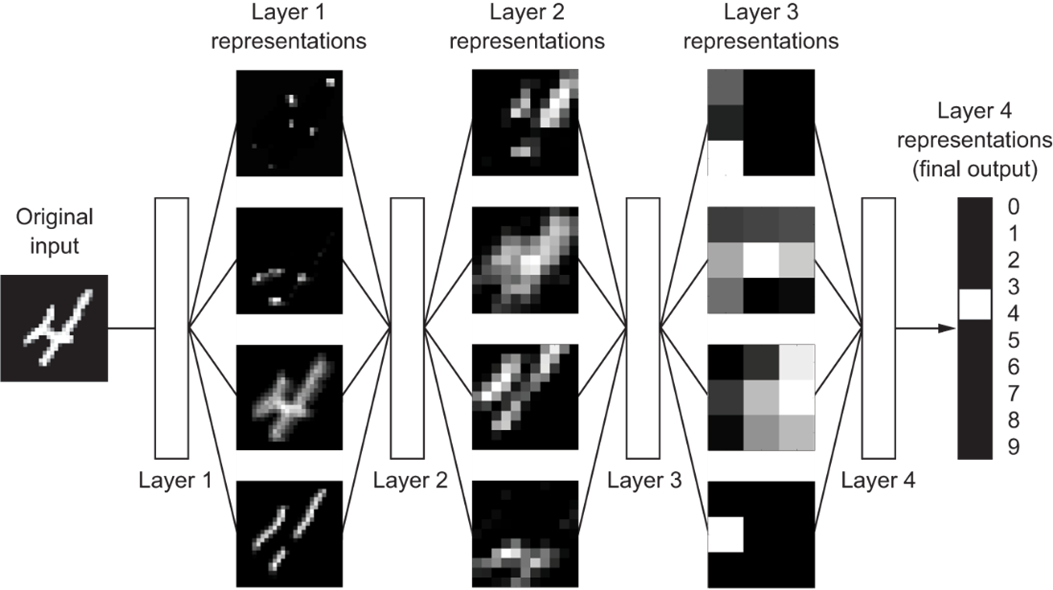

### 1D CNNs

กำหนดลักษณะของ network

filterSize = 5;
numFilters = 32;

classNames = categories(yTrain);
numClasses = numel(classNames);

layers = [ ...
    sequenceInputLayer(1)
    convolution1dLayer(filterSize, numFilters, Padding="causal")
    reluLayer
    layerNormalizationLayer
    convolution1dLayer(filterSize, 2*numFilters, Padding="causal")
    reluLayer
    layerNormalizationLayer
    globalAveragePooling1dLayer
    fullyConnectedLayer(numClasses)
    softmaxLayer]

layers =   10×1 Layer array with layers:

     1   ''   Sequence Input               Sequence input with 1 dimensions
     2   ''   1-D Convolution              32 5 convolutions with stride 1 and padding 'causal'
     3   ''   ReLU                         ReLU
     4   ''   Layer Normalization          Layer normalization
     5   ''   1-D Convolution              64 5 convolutions with stride 1 and padding 'causal'
     6   ''   ReLU                         ReLU
     7   ''   Layer Normalization          Layer normalization
     8   ''   1-D Global Average Pooling   1-D global average pooling
     9   ''   Fully Connected              4 fully connected layer
    10   ''   Softmax                      softmax

กำหนดตัวเลือกการ train และระบุ validation set

options = trainingOptions("adam", ...
    MaxEpochs=120, ...
    MiniBatchSize=64, ...
    InitialLearnRate=0.01, ...
    SequencePaddingDirection="left", ...
    ValidationData={XVal, yVal}, ...
    Plots="training-progress", ...
    Metrics="accuracy", ...
    Verbose=false);

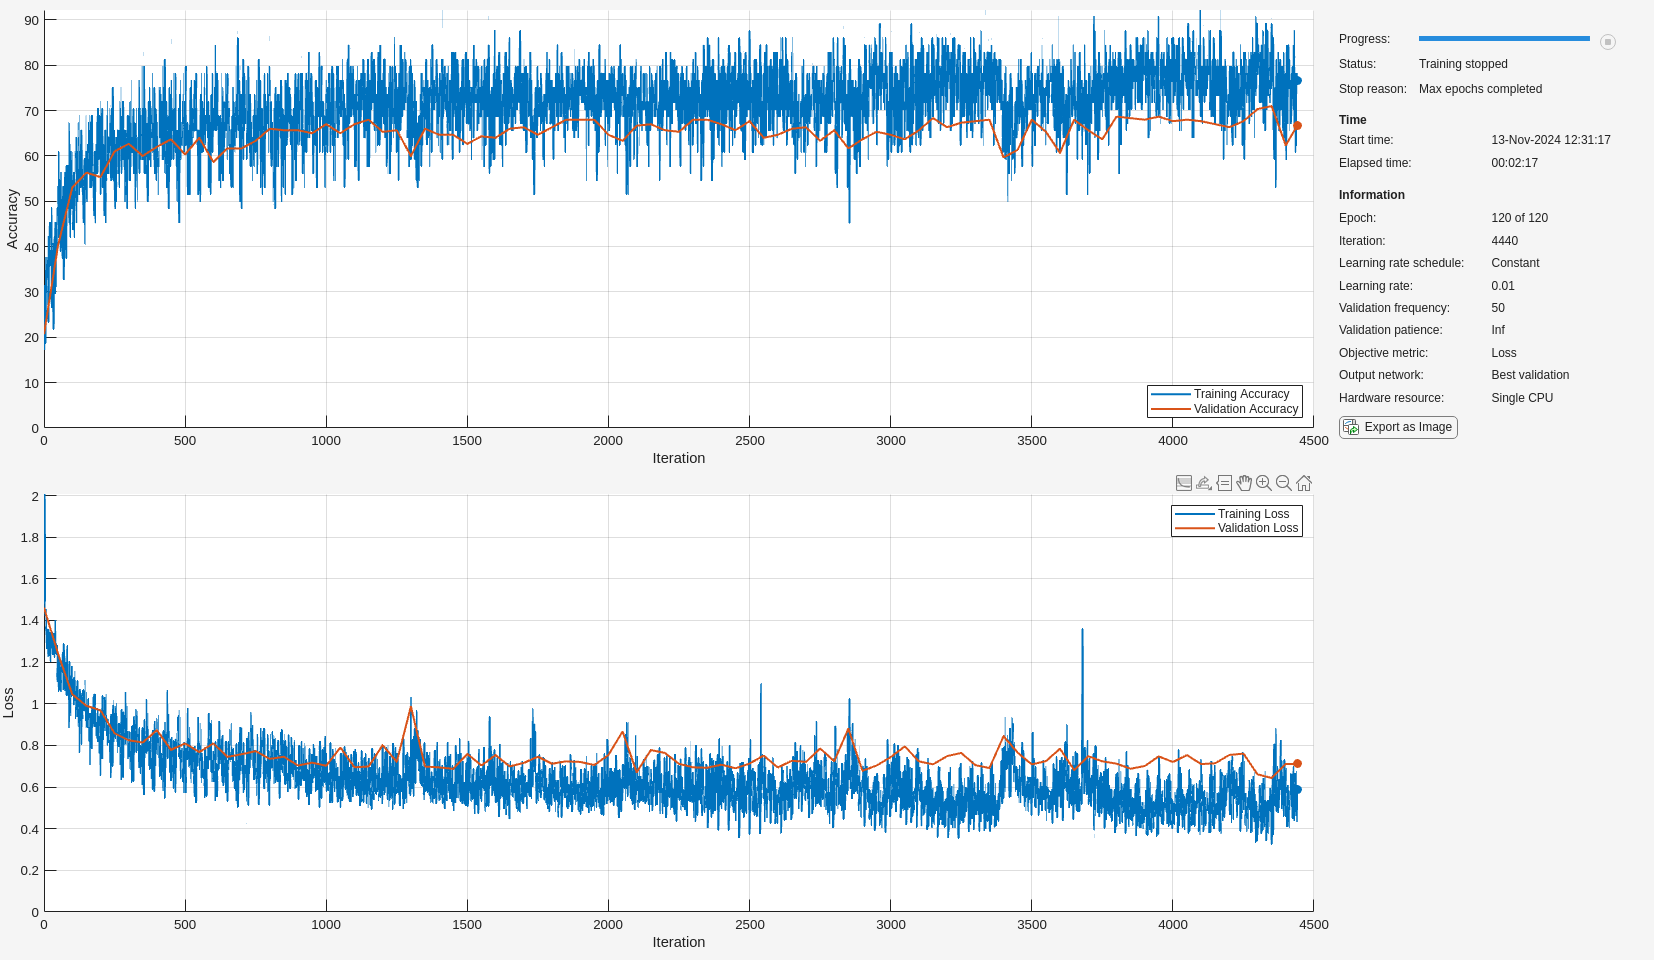

net = trainnet(XTrain, yTrain, layers, "crossentropy", options);

save('net.mat', "net")

load('net.mat')

ทดสอบผลลัพธ์

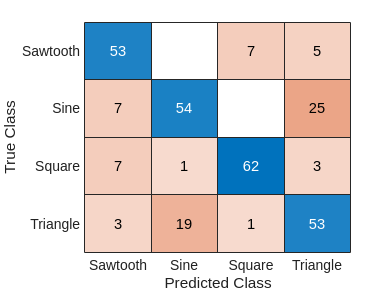

scores = minibatchpredict(net, XTest, SequencePaddingDirection="left");
yPred = scores2label(scores, classNames);
figure

confusionchart(yTest, yPred)

% Compute accuracy
[m, cats] = confusionmat(yTest, yPred);
numCorrect = sum(diag(m));
accuracy = numCorrect / numel(XTest)

accuracy = 0.7400


% Precision, recall, and F1-score
tp = diag(m);
precision = tp ./ sum(m, 2)

precision =     0.8154
    0.6279
    0.8493
    0.6974


recall = tp ./ sum(m, 1)'

recall =     0.7571
    0.7297
    0.8857
    0.6163


f1 = 2 .* precision .* recall ./ (precision + recall)

f1 =     0.7852
    0.6750
    0.8671
    0.6543


f1Mean = mean(f1)

f1Mean = 0.7454

### 2D CNNs

- ใช้ 2D CNN กับ feature ที่เป็น 2 มิติ เช่น spectrogram หรือ MFCC

- ใช้ imageInputLayer หรือ inputLayer แทน sequenceInputLayer

- ใช้ convolution2dLayer แทน convolution1dLayer

- อาจพิจารณาใช้ batchNormalizationLayer แทน layerNormalizationLayer

- ใช้ flattenLayer หรือ globalAveragePooling2dLayer แทน globalAveragePooling1dLayer

## Recurrent neural networks (RNN)

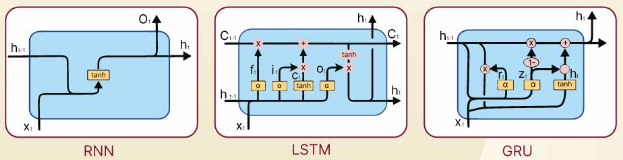

numHiddenUnits = 120;
numClasses = 4;

layers = [
    sequenceInputLayer(1)
    % lstmLayer(numHiddenUnits, OutputMode="sequence")
    lstmLayer(numHiddenUnits, OutputMode="last")
    fullyConnectedLayer(numClasses)
    softmaxLayer]

layers =   4×1 Layer array with layers:

     1   ''   Sequence Input    Sequence input with 1 dimensions
     2   ''   LSTM              LSTM with 120 hidden units
     3   ''   Fully Connected   4 fully connected layer
     4   ''   Softmax           softmax

options = trainingOptions("adam", ...
    MaxEpochs=120, ...
    InitialLearnRate=0.005,...
    GradientThreshold=1, ...
    Shuffle="never", ...
    ValidationData={XVal, yVal}, ...
    Plots="training-progress", ...
    Metrics="accuracy", ...
    Verbose=false);

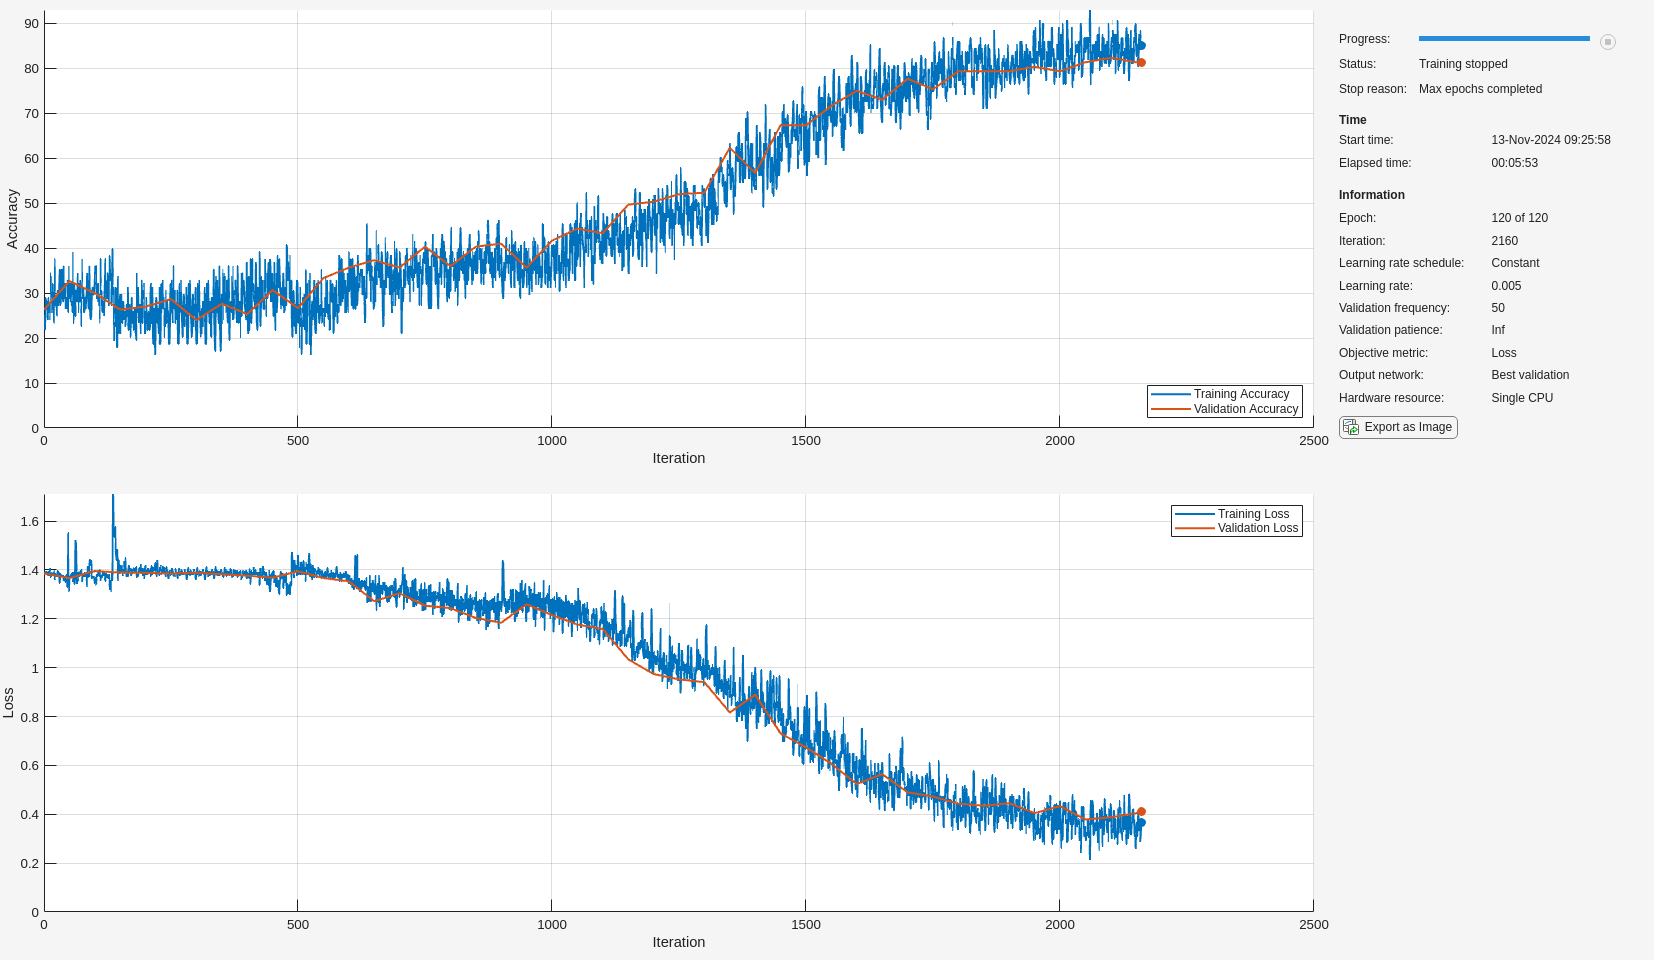

net = trainnet(XTrain, yTrain, layers, "crossentropy", options);

ทดสอบผลลัพธ์

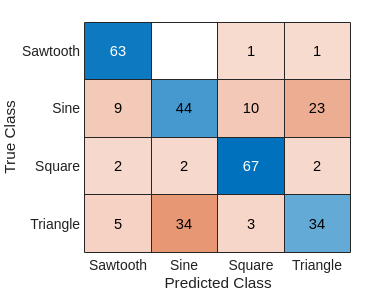

scores = minibatchpredict(net, XTest, SequencePaddingDirection="left");
yPred = scores2label(scores, classNames);
figure
confusionchart(yTest, yPred)

% Compute accuracy
[m, cats] = confusionmat(yTest, yPred);
numCorrect = sum(diag(m));
accuracy = numCorrect / numel(XTest)

accuracy = 0.6933


% Precision, recall, and F1-score
tp = diag(m);
precision = tp ./ sum(m, 2)

precision =     0.9692
    0.5116
    0.9178
    0.4474


recall = tp ./ sum(m, 1)'

recall =     0.7975
    0.5500
    0.8272
    0.5667


f1 = 2 .* precision .* recall ./ (precision + recall)

f1 =     0.8750
    0.5301
    0.8701
    0.5000


f1Mean = mean(f1)

f1Mean = 0.6938

### Sequence-to-sequence classification

ศึกษาเพิ่มเติมที่: [https://www.mathworks.com/help/deeplearning/ug/sequence-to-sequence-classification-using-deep-learning.html](https://www.mathworks.com/help/deeplearning/ug/sequence-to-sequence-classification-using-deep-learning.html)